Laden Sie das Musikstück "AllegroMono44.wav" (oder ein beliebiges Musikstück Ihrer Wahl (.wav file) und wählen Sie ca 1-2 Sekunden des Stückes aus. Filtern Sie die Auswahl des Musikstück mit Hilfe der Fourier Transformierten mit einem Tiefpassfilter, der bis ca. 1 kHz überträgt. Stellen Sie das Original und das gefilterte Stück grafisch dar und vergleichen Sie die Audiowiedergabe. 

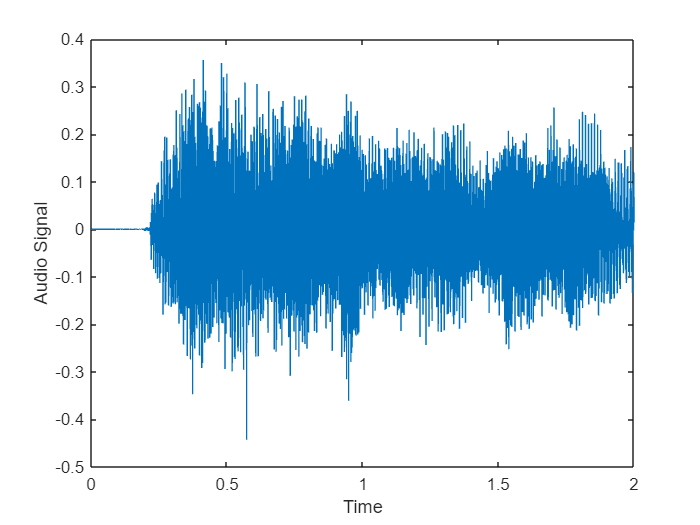

%Ihre Lösung 
clear all;

wavMusikInformationen = audioinfo('AllegroMono44.wav');
[y, Fs] = audioread('AllegroMono44.wav');
tgesamt = 2:seconds(1/Fs):seconds(wavMusikInformationen.Duration);
tgesamt = tgesamt(1:end-1);

% Sampling period
T = 1/Fs;

% Musikteil auswählen
teil = y(10000:98199);
L = length(teil);
t = (0:L-1)*T;

%Anzeigen
figure(1)
plot(t,teil)
xlabel('Time')
ylabel('Audio Signal')

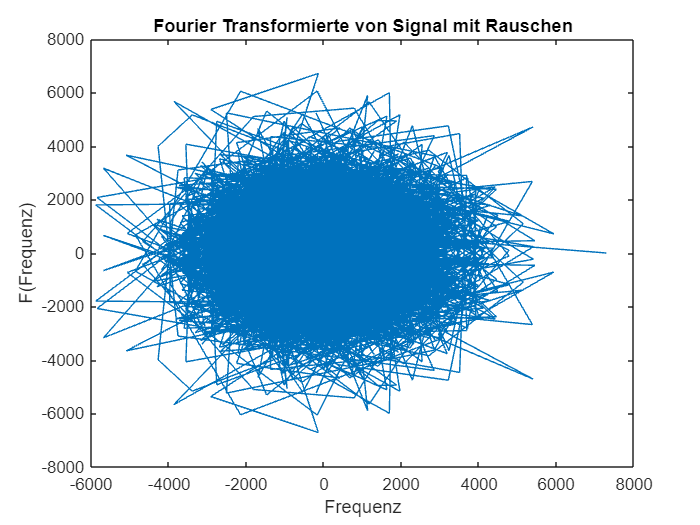

%Abspielen
sound(teil,Fs);
% Fourier Transformation vom Signal
Y=fft(y);
% Normierung
y - 2*Y/length(y); 
figure(2); 
plot(Y);
title('Fourier Transformierte von Signal mit Rauschen'); 
xlabel('Frequenz')
ylabel('F(Frequenz)')

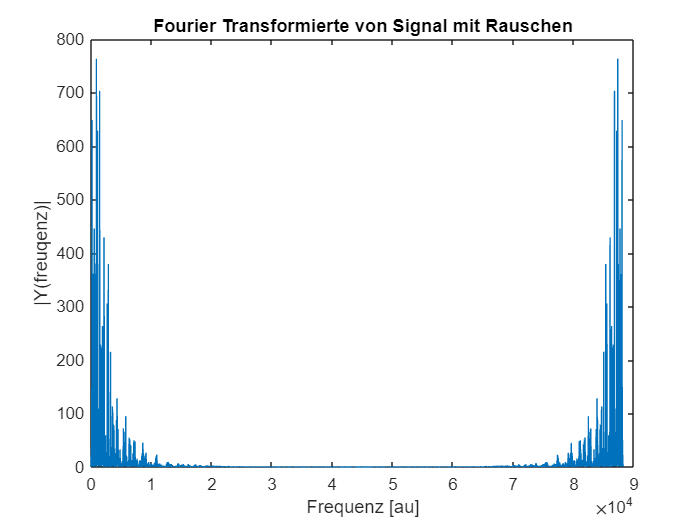


FY = fft(teil);
figure(3)
plot(abs(FY));
title('Fourier Transformierte von Signal mit Rauschen');
xlabel('Frequenz [au]'); 
ylabel('|Y(freuqenz)|');

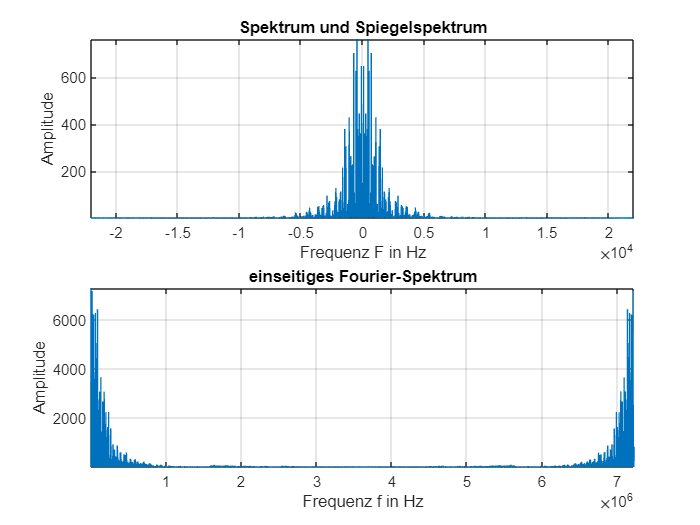

% Frequenzskalierung richtig berechnen
 Fs =1/T; 
Fmax = Fs/2;
Faxis_2side=Fmax * linspace(-1,1,L);
Faxis_1side=Fmax*linspace(0,1,L/2+1);
figure(4); 
subplot(2,1,1);
plot(Faxis_2side, abs(fftshift(FY))); 
axis tight;
title('Spektrum und Spiegelspektrum');
xlabel('Frequenz F in Hz');
ylabel('Amplitude'); 
grid on;

subplot(2,1,2); 
plot(abs(Y));
axis tight;
title('einseitiges Fourier-Spektrum');
xlabel('Frequenz f in Hz');
ylabel('Amplitude');
grid on;

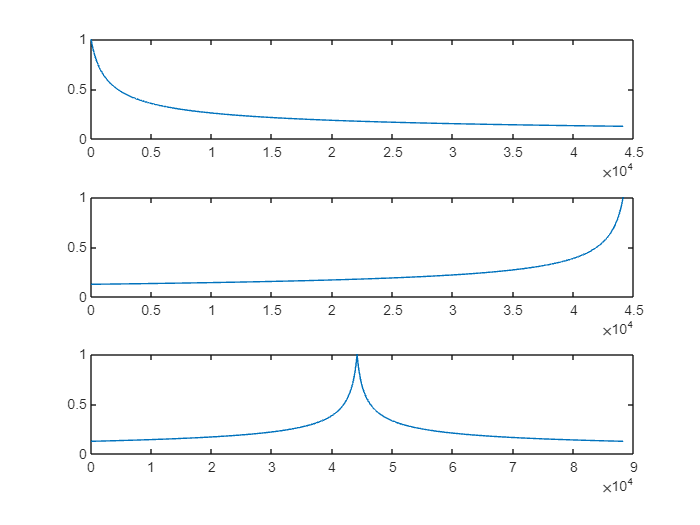

% Tiefpassfilter

filterpos = 1./sqrt(1 + (Faxis_1side - 0)*2.*pi.*0.0000020.*220);
% Filter spiegeln
for i=1:length(filterpos)
    filterneg(i)=filterpos(length(filterpos)-i+1);
end

% Filter von negativer und positiver Seite zusammenbasteln
for i=1:length(filterneg)-1+length(filterpos)-1
    if i<length(filterneg)
        filter(i)=filterneg(i);
    else
        filter(i)=filterpos(i-length(i-filterneg)+1);
    end
end

% Filter normieren
for i=1:length(filter)
    filter(i)=filter(i)/max(filter);
end

figure(6);
subplot(3,1,1); plot(filterpos);
subplot(3,1,2); plot(filterneg);
subplot(3,1,3); plot(filter);